%% Task 4(a) - Bias/Variance Trade-off using polynomial models
clear; clc; close all;

%% Load data from Task 3
data = [
    0.5 480000; 2.0 1850000; 3.0 2100000;
    4.0 1900000; 4.5 3200000; 6.0 1750000;
    7.0 1850000; 9.0 1300000; 10.0 1450000;
    11.0 1400000; 12.0 1150000; 13.0 1100000;
    18.0 1200000; 17.0 1150000; 18.0 950000;
    16.0 1050000; 22.0 900000; 20.0 1200000;
    19.0 1300000; 9.0 1250000; 20.0 1000000;
    22.0 880000; 32.0 820000; 30.0 870000;
    50.0 780000; 35.0 1200000; 40.0 1250000;
    65.0 850000; 10.0 1900000; 8.0 1800000
];

d = data(:,1);
y = data(:,2);

%% Set up polynomial orders and repetitions
orders = 0:20;          % polynomial orders from 0 to 20
numRuns = 100;          % number of random trials
trainRatio = 0.70;      % use 70% of data for fitting
numTrain = round(trainRatio * length(d));

%% Common x-grid for comparing fitted models
dGrid = linspace(min(d), max(d), 200);

%% Store variance result for each polynomial order
modelVariance = zeros(size(orders));

%% Repeat fitting for each polynomial order
for k = 1:length(orders)

    order = orders(k);

    % Store predicted curves from each random run
    allPredictions = zeros(numRuns, length(dGrid));

    for r = 1:numRuns

        % Randomly choose training data points
        idx = randperm(length(d), numTrain);

        dTrain = d(idx);
        yTrain = y(idx);

        % Fit polynomial model
        p = polyfit(dTrain, yTrain, order);

        % Predict on the common grid
        yPred = polyval(p, dGrid);

        % Store this fitted curve
        allPredictions(r, :) = yPred;
    end

    % Compute variance between fitted curves for this order
    % Variance is calculated at each grid point, then averaged
    modelVariance(k) = mean(var(allPredictions, 0, 1));
end

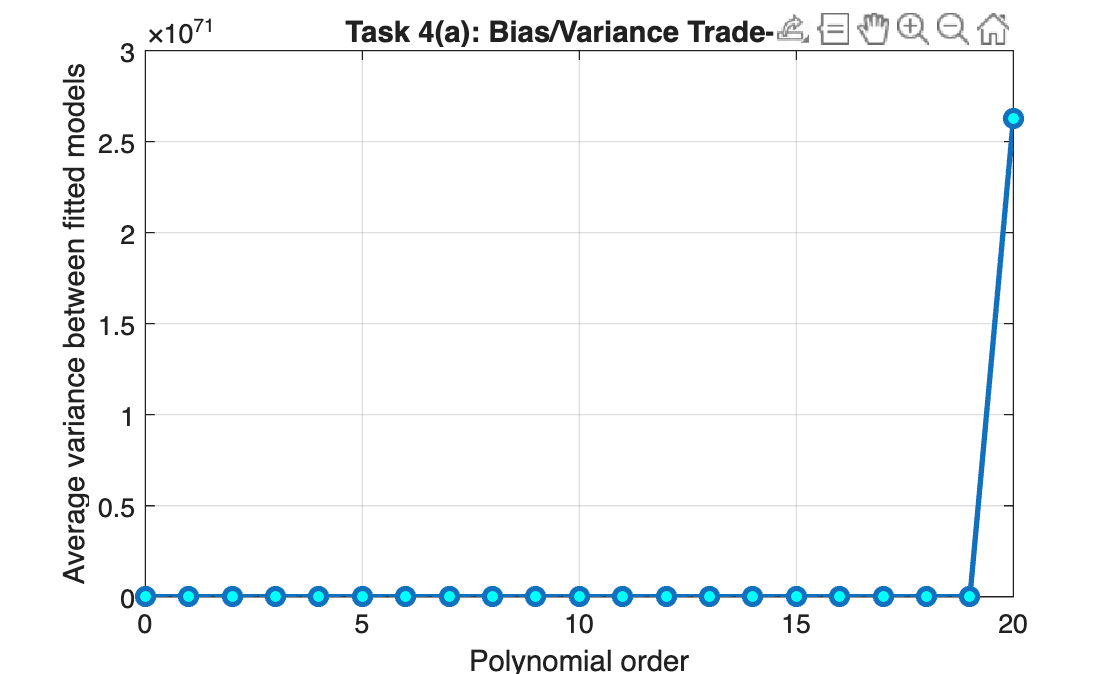


%% Plot variance as a function of polynomial order
figure;
plot(orders, modelVariance, 'o-', 'LineWidth', 2, 'MarkerFaceColor', 'cyan');

xlabel('Polynomial order');
ylabel('Average variance between fitted models');
title('Task 4(a): Bias/Variance Trade-off');
grid on;